## divide train set and test set

data = X;
label = y;

ratio = 0.7;
num_train = floor(length(label)*ratio); 
choose = randperm(length(label));

train_data  = data(choose(1:num_train), :);
train_label = label(choose(1:num_train));
test_data   = data(choose(num_train+1:end), :);
test_label  = label(choose(num_train+1:end));

## grid search

*
optimization finished, #iter = 37
nu = 0.478420
obj = -8.705577, rho = 0.017879
nSV = 59, nBSV = 52
*
optimization finished, #iter = 23
nu = 0.175680
obj = -2.662974, rho = 0.080224
nSV = 25, nBSV = 16
*
optimization finished, #iter = 37
nu = 0.474102
obj = -9.740591, rho = -0.065708
nSV = 54, nBSV = 49
*
optimization finished, #iter = 25
nu = 0.153882
obj = -2.467446, rho = 0.059273
nSV = 23, nBSV = 14
*
optimization finished, #iter = 40
nu = 0.376636
obj = -7.662292, rho = -0.040002
nSV = 50, nBSV = 40
*
optimization finished, #iter = 24
nu = 0.203948
obj = -3.168466, rho = -0.022266
nSV = 27, nBSV = 20
Total nSV = 124
*
optimization finished, #iter = 43
nu = 0.476536
obj = -8.246460, rho = 0.106248
nSV = 58, nBSV = 51
*
optimization finished, #iter = 42
nu = 0.168485
obj = -2.534105, rho = 0.106685
nSV = 26, nBSV = 11
*
optimization finished, #iter = 36
nu = 0.473516
obj = -9.383622, rho = 0.098075
nSV = 53, nBSV = 47
*
optimization finished, #iter = 40
nu = 0.154884
obj = -2.4084

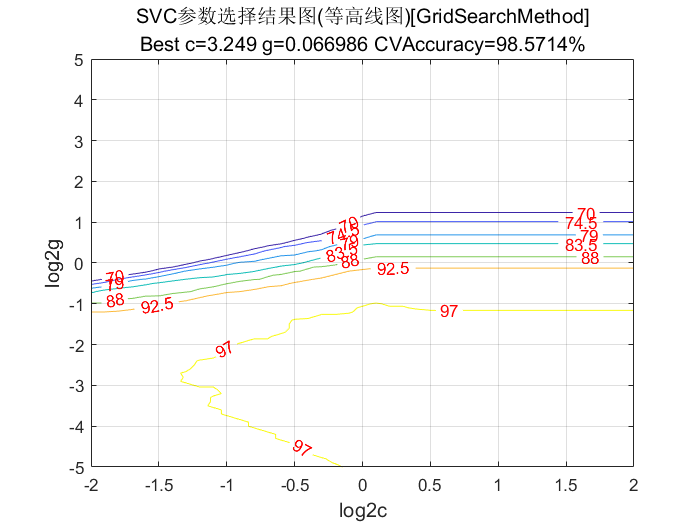

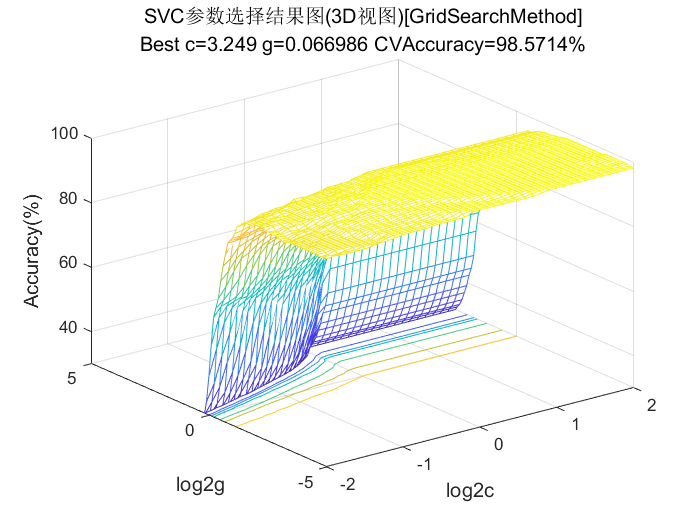

tic
[bestacc,bestc,bestg] = svm_gridsearch(train_label,train_data);

toc

历时 1029.514841 秒。


## train model

s = 0;
t = 2;
c = bestc;
g = bestg;
options = [' -s ',num2str(s),' -t ',num2str(t),' -c ',num2str(c),' -g ',num2str(g)];
model = libsvmtrain(train_label, train_data, options); 

*
optimization finished, #iter = 129
nu = 0.059232
obj = -13.663273, rho = -0.162675
nSV = 29, nBSV = 0
*
optimization finished, #iter = 70
nu = 0.019662
obj = -4.343596, rho = 0.032099
nSV = 25, nBSV = 0
*
optimization finished, #iter = 116
nu = 0.143626
obj = -37.979509, rho = -0.295098
nSV = 35, nBSV = 12
*
optimization finished, #iter = 53
nu = 0.017835
obj = -4.229795, rho = 0.061860
nSV = 26, nBSV = 0
*
optimization finished, #iter = 113
nu = 0.095608
obj = -24.995360, rho = 0.065437
nSV = 28, nBSV = 6
*
optimization finished, #iter = 68
nu = 0.025108
obj = -5.628808, rho = -0.056326
nSV = 24, nBSV = 0
Total nSV = 94


## predict test set

[train_pred_label, train_acc, ~]...
           = libsvmpredict(train_label, train_data, model);

Accuracy = 99.6429% (279/280) (classification)


[test_pred_label, test_acc, ~]...
           = libsvmpredict(test_label, test_data, model);

Accuracy = 98.3333% (118/120) (classification)


## confusion matrix

% plotconfusion(test_label.', test_pred_label.');

# model = libsvmtrain(label, data, ‘option’)

# [predicted_label, accuracy,decision_values] = libsvmpredict(y_test, x_test, model)

% options:
% -s svm_type : set type of SVM (default 0)
% 	0 -- C-SVC		(multi-class classification)
% 	1 -- nu-SVC		(multi-class classification)
% 	2 -- one-class SVM
% 	3 -- epsilon-SVR	(regression)
% 	4 -- nu-SVR		(regression)
% -t kernel_type : set type of kernel function (default 2)
% 	0 -- linear: u'*v
% 	1 -- polynomial: (gamma*u'*v + coef0)^degree
% 	2 -- radial basis function: exp(-gamma*|u-v|^2)
% 	3 -- sigmoid: tanh(gamma*u'*v + coef0)
% 	4 -- precomputed kernel (kernel values in training_set_file)
% -d degree : set degree in kernel function (default 3)
% -g gamma : set gamma in kernel function (default 1/num_features)  
%            gamma越大，支持向量越少，过拟合
% -r coef0 : set coef0 in kernel function (default 0)
% -c cost : set the parameter C of C-SVC, epsilon-SVR, and nu-SVR (default 1)
%           C是惩罚系数（正则化参数的倒数），即对误差的宽容度，c越大，容易过拟合
% -n nu : set the parameter nu of nu-SVC, one-class SVM, and nu-SVR (default 0.5)
% -p epsilon : set the epsilon in loss function of epsilon-SVR (default 0.1)
% -m cachesize : set cache memory size in MB (default 100)
% -e epsilon : set tolerance of termination criterion (default 0.001)
% -h shrinking : whether to use the shrinking heuristics, 0 or 1 (default 1)
% -b probability_estimates : whether to train a SVC or SVR model for probability estimates, 0 or 1 (default 0)
% -wi weight : set the parameter C of class i to weight*C, for C-SVC (default 1)
% -v n: n-fold cross validation mode(default 5)
% -q : quiet mode (no outputs)

% iter为迭代次数，
% nu 与前面的操作参数-n nu 相同，
% obj为SVM文件转换为的二次规划求解得到的最小值，
% rho 为判决函数的常数项b，
% nSV 为支持向量个数，
% nBSV为边界上的支持向量个数，
% Total nSV为支持向量总个数。
% 训练后的模型保存为文件*.model，用记事本打开其内容如下：
% svm_type c_svc % 训练所采用的svm类型，此处为C- SVC
% kernel_type rbf %训练采用的核函数类型，此处为RBF核
% gamma 0.0769231 %设置核函数中的g ，默认值为1/ k
% nr_class 2 %分类时的类别数，此处为两分类问题
% total_sv 132 %总共的支持向量个数
% rho 0.424462 %决策函数中的常数项b
% label 1 -1%类别标签
% nr_sv 64 68 %各类别标签对应的支持向量个数